# Bootstraping and Forecasting on time series AR models

Bootstrap methods are widely used to assess sampling variability and construct confidence intervals when analytical formulas are difficult or unreliable.

However, standard bootstrap resampling assumes **independent and identically distributed (iid)** data, which is inappropriate for **dependent** (autocorrelated) time series commonly observed in financial and economic contexts.

To address this, the **MBB** resamples **blocks** of consecutive observations, thereby preserving short-range dependence.

This exercise provides a unified, hands-on exploration of modern forecasting and resampling techniques for autoregressive time-series models. We begin by generating two artificial datasets: an independent and identically distributed (i.i.d.) series and a dependent series following an AR(1) process. These controlled environments allow us to investigate how temporal dependence affects the performance of bootstrap methods. In particular, we compare the simple i.i.d. bootstrap, which ignores serial correlation, with the Moving Block Bootstrap (MBB), which resamples blocks of consecutive observations to preserve the time-series structure.

Building on these insights, we turn to model selection using out-of-sample forecasting. Several strategies are considered: recursive estimation, rolling-window forecasting, and k-fold cross-validation adapted for time series. By evaluating the forecasting accuracy of AR(p) models with varying lag orders, we highlight how different resampling and validation schemes behave under dependence, and how they guide the choice of an appropriate AR order.

Overall, the exercise illustrates key principles of time-series resampling, the importance of dependence-aware bootstrap methods, and the role of out-of-sample performance in selecting parsimonious and reliable forecasting models.

We generate two time series:

- **U** – a random variable drawn from a Normal distribution with mean 5 and standard deviation 3.

- **Z** – an autoregressive process of order one, AR(1), with autoregressive coefficient 0.8.

The goal is to understand how different data-generating mechanisms (independent white noise vs. a persistent AR process) affect the structure and statistical properties of simulated time series.

These simulated series can later be used to explore properties such as autocorrelation, stationarity, or forecastability.

Set random seed for reproducibility

rng(1985);


Sample size

N = 200;


 Simulate X ~ N(5, 3^2)

X = 5 + 3 * randn(N, 1);


% Simulate AR(1) process $Y_t = 0.8\,Y_{t-1} + e_t$

Mdl = arima('Constant',0,'AR',0.8,'Variance',1);
Y = simulate(Mdl, N);


%Combine into table with variable names

U = X;
Z = Y;
data = table(U, Z);


Write to CSV file (optional)

writetable(data, 'data.csv');

- Inspect their autocorrelation functions (ACFs) to diagnose dependence.

- Apply the Moving Block Bootstrap to the dependent series Z and compare it with incorrect iid resampling.

- Use the MBB to construct **bootstrap confidence intervals** for the standard deviation of Z.

Through this exercise, we highlight the importance of using appropriate bootstrap techniques for time-dependent data and illustrate how ignoring dependence can lead to misleading inference.

How many observations?

N = height(data);   % same as numel(U)

 Check dependence structure: ACFs of U and Z

Requires Econometrics Toolbox for autocorr. 

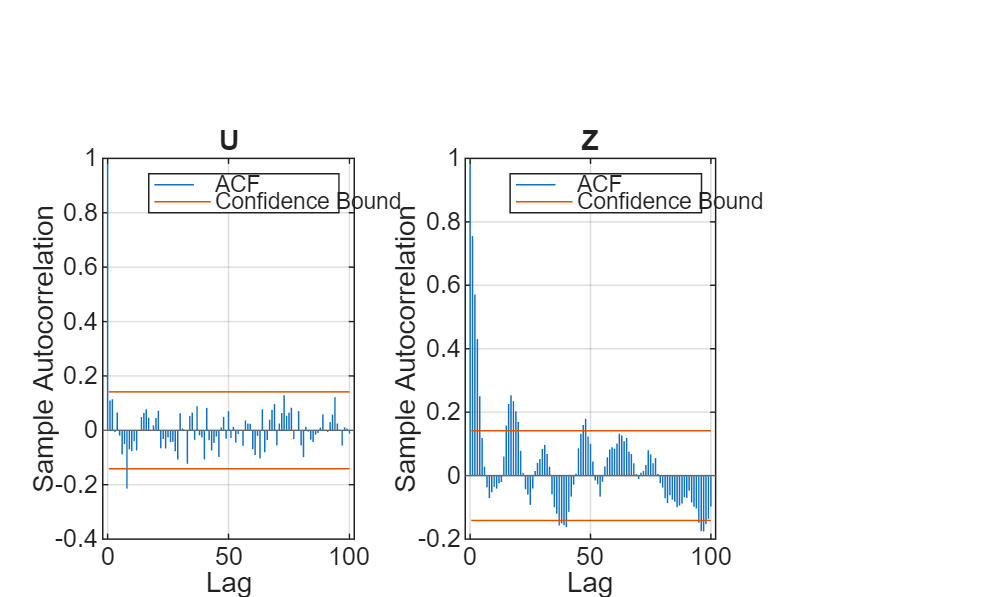


figure('Name','ACFs: U and Z');
tiledlayout(1,2);

data = {U, Z};
titles = {'U','Z'};

for i = 1:2
    nexttile;
    autocorr(data{i}, NumLags=100);
    title(titles{i});

    % remove the big dots
    h = findall(gca, 'Type', 'Stem');
    set(h, 'Marker', 'none');
end

Interpretation:

 U ~ iid (ACF near 0 after lag 0) -> use iid resampling

 Z shows dependence (positive ACF at small lags) -> use block resampling

 Moving Block Bootstrap (MBB) block length

bl = ceil(N^(1/3));


Create one MBB resample of Z and compare ACFs

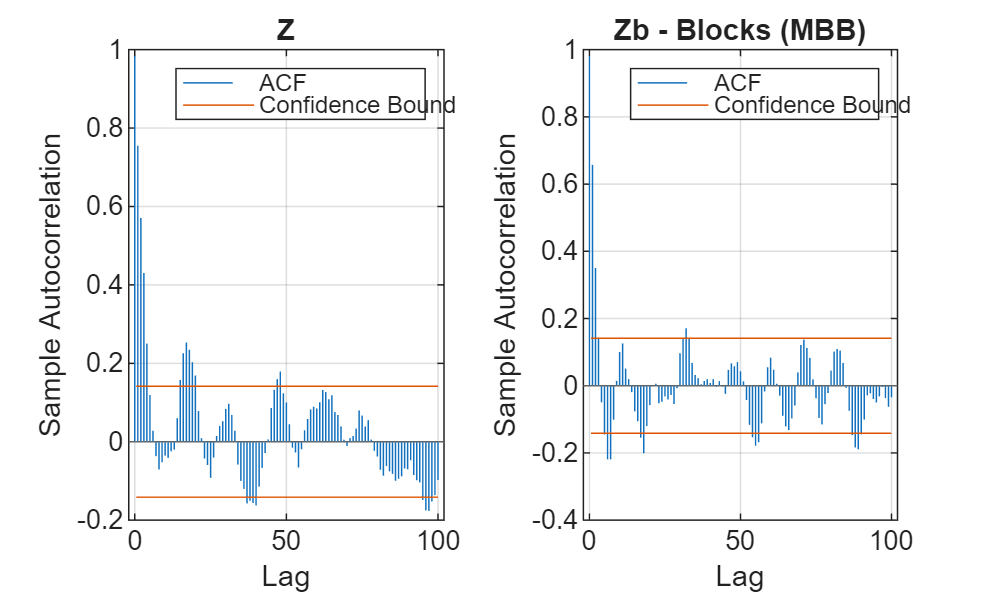


Zb = MBB(Z, bl);

figure('Name','ACFs: Z vs Zb (MBB)');
tiledlayout(1,2);

data = {Z, Zb};
titles = {'Z', 'Zb - Blocks (MBB)'};

for i = 1:2
    nexttile;
    autocorr(data{i}, NumLags=100);
    title(titles{i});

    % remove markers
    h = findall(gca, 'Type', 'Stem');
    set(h, 'Marker', 'none');
end

What if we mistakenly use iid resampling on Z?

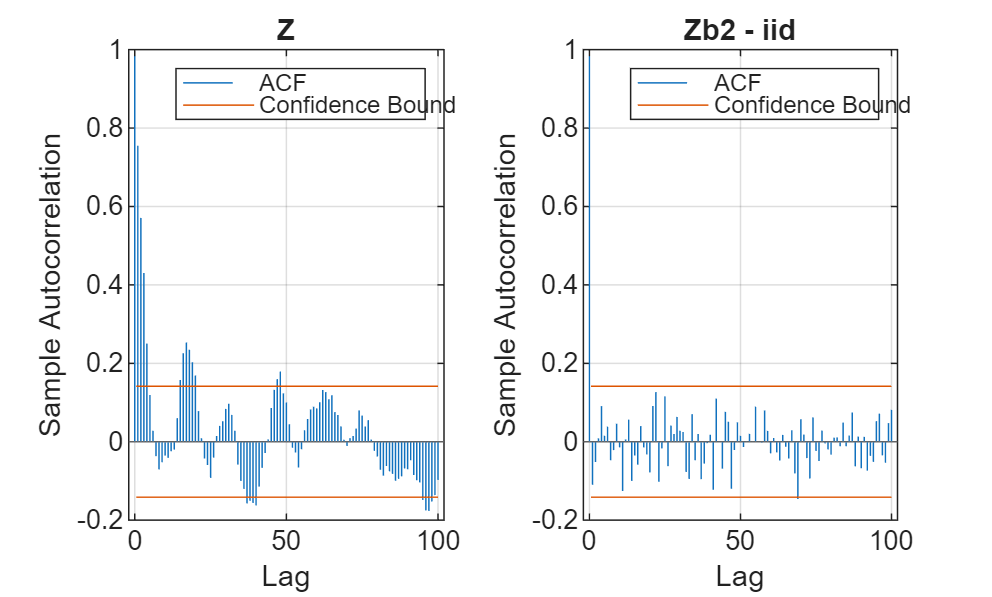

sel = randi(N, N, 1);   
Zb2 = Z(sel);

figure('Name','ACFs: Z vs Zb2 (iid)');
tiledlayout(1,2);

data = {Z, Zb2};
titles = {'Z', 'Zb2 - iid'};

for i = 1:2
    nexttile;
    autocorr(data{i}, NumLags=100);
    title(titles{i});

    % Remove the big dots
    h = findall(gca, 'Type', 'Stem');
    set(h, 'Marker', 'none');
end

Note: iid resampling destroys persistence in Z.

 Bootstrap CI for the true SD of Z using MBB with b = N^(1/3)

B  = 2000;
Bsd = NaN(B,1);

for i = 1:B
    Zb = MBB(Z, bl);
    Bsd(i) = std(Zb);              % MATLAB std uses n-1 by default (same as R's sd)
    if mod(i,50)==0
        fprintf('Now done %d of %d bootstraps\n', i, B);
    end
end

Now done 50 of 2000 bootstraps
Now done 100 of 2000 bootstraps
Now done 150 of 2000 bootstraps
Now done 200 of 2000 bootstraps
Now done 250 of 2000 bootstraps
Now done 300 of 2000 bootstraps
Now done 350 of 2000 bootstraps
Now done 400 of 2000 bootstraps
Now done 450 of 2000 bootstraps
Now done 500 of 2000 bootstraps
Now done 550 of 2000 bootstraps
Now done 600 of 2000 bootstraps
Now done 650 of 2000 bootstraps
Now done 700 of 2000 bootstraps
Now done 750 of 2000 bootstraps
Now done 800 of 2000 bootstraps
Now done 850 of 2000 bootstraps
Now done 900 of 2000 bootstraps
Now done 950 of 2000 bootstraps
Now done 1000 of 2000 bootstraps
Now done 1050 of 2000 bootstraps
Now done 1100 of 2000 bootstraps
Now done 1150 of 2000 bootstraps
Now done 1200 of 2000 bootstraps
Now done 1250 of 2000 bootstraps
Now done 1300 of 2000 bootstraps
Now done 1350 of 2000 bootstraps
Now done 1400 of 2000 bootstraps
Now done 1450 of 2000 bootstraps
Now done 1500 of 2000 bootstraps
Now done 1550 of 2000 bootstra

Observed sample SD

obsSD = std(Z)

obsSD = 1.5275

90% bootstrap CI for the true SD

ci90 = prctile(Bsd, [5 95])

ci90 =     1.3167    1.7312


- The repeated MBB resamples generate a distribution of bootstrap standard deviations 

- The **90% confidence interval** from the empirical quantiles should include the true sample SD of Z.

- This illustrates how MBB can be used to construct **confidence intervals** that account for serial dependence.

For the **series without dependence (U)** the two bootstrap methods give essentially the same result.

The ACF estimates at non-zero lags are small and the corresponding bootstrap confidence bands are centred around zero and are quite narrow. Almost all autocorrelation coefficients lie inside the bands, which is what we expect for an i.i.d. series.

For the **AR(1) series (Z)** the picture is different:

- The **simple i.i.d. bootstrap** resamples observations independently and therefore destroys the time-series dependence. Its confidence intervals look similar to those of U: they are centred near zero and are too narrow. As a result, the bands do **not** reflect the true persistence in Z and tend to underestimate the uncertainty of the ACF/parameter estimates.

- The **Moving Block Bootstrap (MBB)** resamples blocks of consecutive observations and therefore preserves the local dependence structure. The resulting confidence intervals are wider and shifted in line with the sample ACF of Z (e.g. clearly away from zero at low lags), better capturing the variability one would expect from an AR(1) process.

So, the main conclusion about the **confidence intervals** is:

For independent data both i.i.d. bootstrap and MBB give similar, reasonable intervals.

For dependent data (AR(1)), the i.i.d. bootstrap produces misleadingly narrow intervals because it ignores serial correlation, whereas the MBB intervals correctly account for dependence and therefore provide more reliable inference.

Performs **recursive and rolling forecasts** for AR(1)–AR(5) models and compares RMSFEs (Root Mean Squared Forecast Errors).

Model Zt as an AR(P) process, where the order P is selected based on a rolling forecasting experiment for h = 1 and a window size of 40 obs. Try orders P=1,2,3,4,5.

%% Forecasting setup
h = 1;          % Forecast horizon
W = 40;         % Window length for recursive / rolling estimation
pmax = 5;       % Max AR order

%% Create storage for forecasts
fcsts = NaN(N, pmax);

%% ========== RECURSIVE FORECASTING ==========
fprintf('Starting recursive forecasting...\n');

Starting recursive forecasting...



for i = W:(N - h)
    Zin = Z(1:i);

    for p = 1:pmax
        % Estimate AR(p)
        Mdl = arima('Constant', 0, 'ARLags', 1:p, 'Variance', NaN);
        MdlFit = estimate(Mdl, Zin, 'Display', 'off');

        % 1-step-ahead forecast
        YF = forecast(MdlFit, h, 'Y0', Zin);
        fcsts(i + h, p) = YF(h);
    end

    if mod(i, 10) == 0
        fprintf('Recursive: Done %d of %d\n', i, N - h);
    end
end

Recursive: Done 40 of 199
Recursive: Done 50 of 199
Recursive: Done 60 of 199
Recursive: Done 70 of 199
Recursive: Done 80 of 199
Recursive: Done 90 of 199
Recursive: Done 100 of 199
Recursive: Done 110 of 199
Recursive: Done 120 of 199
Recursive: Done 130 of 199
Recursive: Done 140 of 199
Recursive: Done 150 of 199
Recursive: Done 160 of 199
Recursive: Done 170 of 199
Recursive: Done 180 of 199
Recursive: Done 190 of 199



%% Forecast errors and RMSFE for recursive case
ferr = repmat(Z, 1, pmax) - fcsts;
ferr = ferr(~any(isnan(ferr), 2), :);
RMSFE_rec = sqrt(mean(ferr.^2, 1));

disp('RMSFE (Recursive):');

RMSFE (Recursive):


disp(array2table(RMSFE_rec, 'VariableNames', strcat('AR', string(1:pmax))));

      AR1        AR2       AR3        AR4        AR5  
    _______    _______    ______    _______    _______

    0.98144    0.98732    0.9914    0.97859    0.98537




%% ========== ROLLING FORECASTING ==========
fprintf('Starting rolling forecasting...\n');

Starting rolling forecasting...


fcsts = NaN(N, pmax);   % reset forecasts

for i = W:(N - h)
    Zin = Z((i - W + 1):i);

    for p = 1:pmax
        % Estimate AR(p)
        Mdl = arima('Constant', 0, 'ARLags', 1:p, 'Variance', NaN);
        MdlFit = estimate(Mdl, Zin, 'Display', 'off');

        % 1-step-ahead forecast
        YF = forecast(MdlFit, h, 'Y0', Zin);
        fcsts(i + h, p) = YF(h);
    end

    if mod(i, 10) == 0
        fprintf('Rolling: Done %d of %d\n', i, N - h);
    end
end

Rolling: Done 40 of 199
Rolling: Done 50 of 199
Rolling: Done 60 of 199
Rolling: Done 70 of 199
Rolling: Done 80 of 199
Rolling: Done 90 of 199
Rolling: Done 100 of 199
Rolling: Done 110 of 199
Rolling: Done 120 of 199
Rolling: Done 130 of 199
Rolling: Done 140 of 199
Rolling: Done 150 of 199
Rolling: Done 160 of 199
Rolling: Done 170 of 199
Rolling: Done 180 of 199
Rolling: Done 190 of 199



%% Forecast errors and RMSFE for rolling case
ferr = repmat(Z, 1, pmax) - fcsts;
ferr = ferr(~any(isnan(ferr), 2), :);
RMSFE_roll = sqrt(mean(ferr.^2, 1));

disp('RMSFE (Rolling):');

RMSFE (Rolling):


disp(array2table(RMSFE_roll, 'VariableNames', strcat('AR', string(1:pmax))));

     AR1       AR2       AR3       AR4       AR5 
    ______    ______    ______    ______    _____

    0.9967    1.0041    1.0145    1.0079    1.024



This exercise compared the out-of-sample forecasting performance of autoregressive models with different lag lengths under **recursive** and **rolling** estimation schemes.

The results show that, in most cases, the **AR(1)** model achieves the lowest **Root Mean Squared Forecast Error (RMSFE)**, implying that a simple first-order autoregressive process provides the most accurate one-step-ahead forecasts for this dataset.

The similarity between the recursive and rolling RMSFEs suggests that the underlying process is **relatively stable** over time—using all available information (recursive) or a fixed-length window (rolling) leads to comparable predictive accuracy.

**The data-generating process is stable enough that using all past data (recursive) or only the most recent data (rolling) makes little difference.**

**In other words, the series does not show strong structural changes over time, so both methods learn essentially the same dynamics.**

If instead the rolling forecasts were noticeably better, that would indicate **time-varying dynamics** or **structural change** in the series.

Overall, this analysis highlights the importance of out-of-sample evaluation when selecting forecasting models: increasing model complexity (adding more lags) does not necessarily improve predictive performance, and in stable environments, **parsimonious models such as AR(1)** are often preferred.

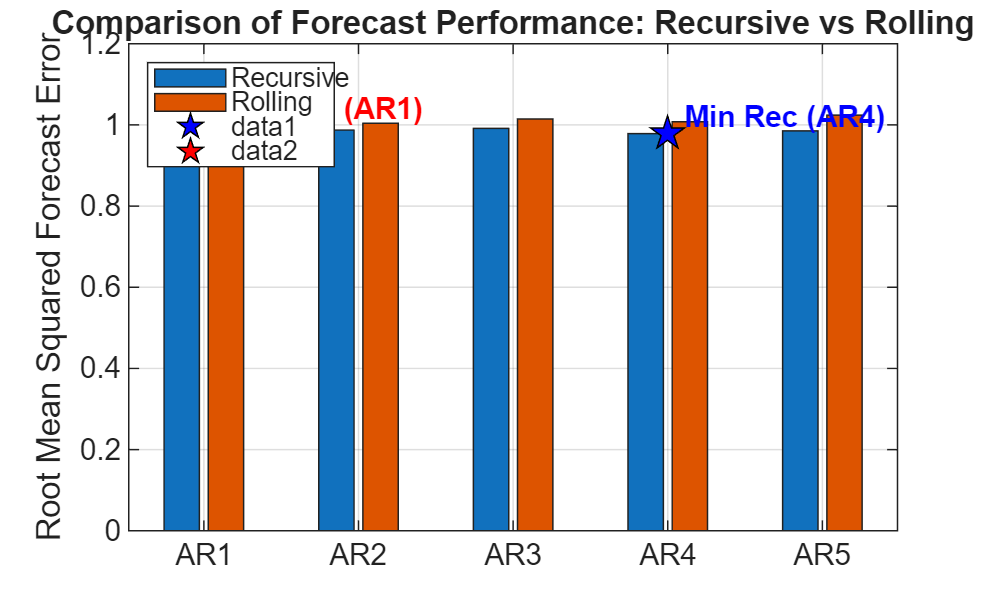

%% ----- Compare Recursive vs Rolling RMSFE -----



ARorders = 1:length(RMSFE_rec);  % AR(1)...AR(5)

figure;
bar([RMSFE_rec; RMSFE_roll]', 'grouped');  % grouped bar chart
xticklabels("AR" + string(ARorders));
ylabel('Root Mean Squared Forecast Error');
legend({'Recursive','Rolling'}, 'Location','northwest');
title('Comparison of Forecast Performance: Recursive vs Rolling');
grid on;

%% Highlight the best model (lowest RMSFE) in each scheme
[minRec, idxRec] = min(RMSFE_rec);
[minRoll, idxRoll] = min(RMSFE_roll);

hold on;
% Add markers for the minimum bars
plot(idxRec, minRec, 'kp', 'MarkerFaceColor','blue', 'MarkerSize',12);
plot(idxRoll, minRoll, 'kp', 'MarkerFaceColor','red', 'MarkerSize',12);
text(idxRec, minRec, sprintf('  Min Rec (AR%d)', idxRec), 'Color','blue', 'FontWeight','bold', 'VerticalAlignment','bottom');
text(idxRoll, minRoll, sprintf('  Min Roll (AR%d)', idxRoll), 'Color','red', 'FontWeight','bold', 'VerticalAlignment','bottom');

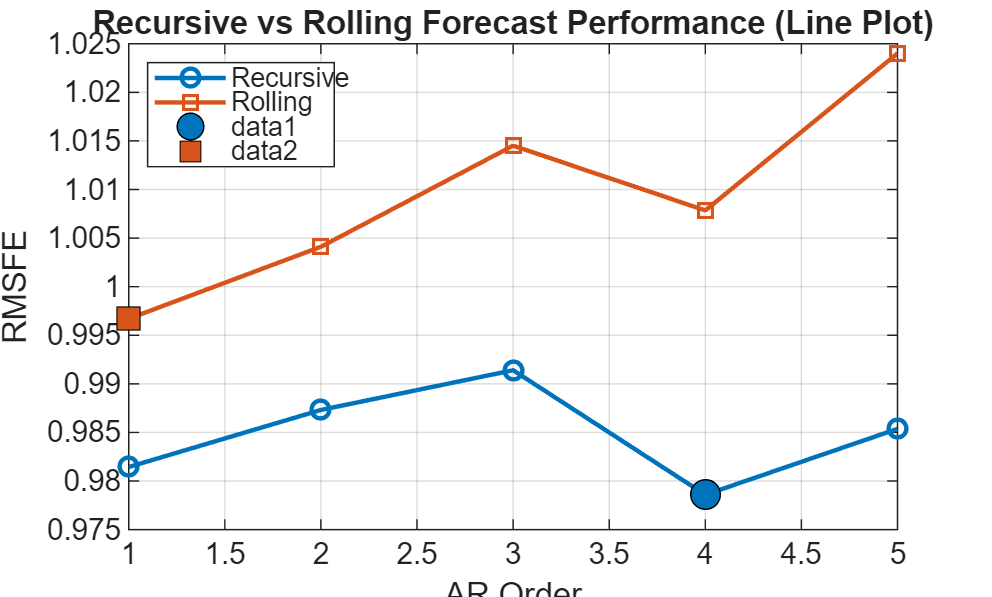


%% Optional: line version for trend comparison
figure;
plot(ARorders, RMSFE_rec, '-o', 'LineWidth',1.5, 'Color',[0 0.45 0.74]); hold on;
plot(ARorders, RMSFE_roll, '-s', 'LineWidth',1.5, 'Color',[0.85 0.33 0.1]);
xlabel('AR Order'); ylabel('RMSFE');
legend('Recursive','Rolling','Location','northwest');
title('Recursive vs Rolling Forecast Performance (Line Plot)');
grid on;

% Highlight minima in the line chart
plot(idxRec, minRec, 'o', 'MarkerEdgeColor','k', 'MarkerFaceColor',[0 0.45 0.74], 'MarkerSize',10);
plot(idxRoll, minRoll, 's', 'MarkerEdgeColor','k', 'MarkerFaceColor',[0.85 0.33 0.1], 'MarkerSize',10);

The recursive forecasts achieve their lowest RMSFE at AR(4), while the rolling window favors AR(1). Since the process is stable, the recursive method is more appropriate, so AR(4) is the preferred model.

However, one might notice that the differences in forecast accuracy between AR(1) and AR(4) are very small in this dataset, so even slight estimation or sample-window variations can cause one or the other to appear marginally better.

This last aort shows how to use **k-fold cross-validation (CV)** to evaluate and compare the out-of-sample forecasting performance of autoregressive (AR) models with different lag orders.

The focus is on selecting the optimal order p for an AR(p) process based on predictive accuracy rather than purely in-sample fit criteria.

In time series forecasting, information from past observations is used to predict future values.

While traditional model selection techniques (such as AIC or BIC) assess goodness of fit within the sample, cross-validation provides a **data-driven, out-of-sample** evaluation of predictive performance.

By dividing the dataset into k contiguous folds, we repeatedly estimate the model on one subset (training fold) and compute forecast errors on the remaining folds (validation sets).

This procedure mimics the real-world situation where models are estimated on historical data and tested on unseen future observations.

- The time series  is partitioned into k=5 folds of equal size.

- For each AR order p=1,…,5  the model is estimated on one fold and evaluated on the remaining folds.

- The **Root Mean Squared Forecast Error (RMSFE)** is computed as a performance metric.

- Averaging RMSFEs across folds provides a robust indicator of which AR model delivers the best predictive accuracy.

This approach allows for a practical comparison of model complexity versus forecasting performance.

A lower RMSFE indicates superior out-of-sample accuracy, guiding the selection of the most parsimonious AR specification that balances fit and generalization.

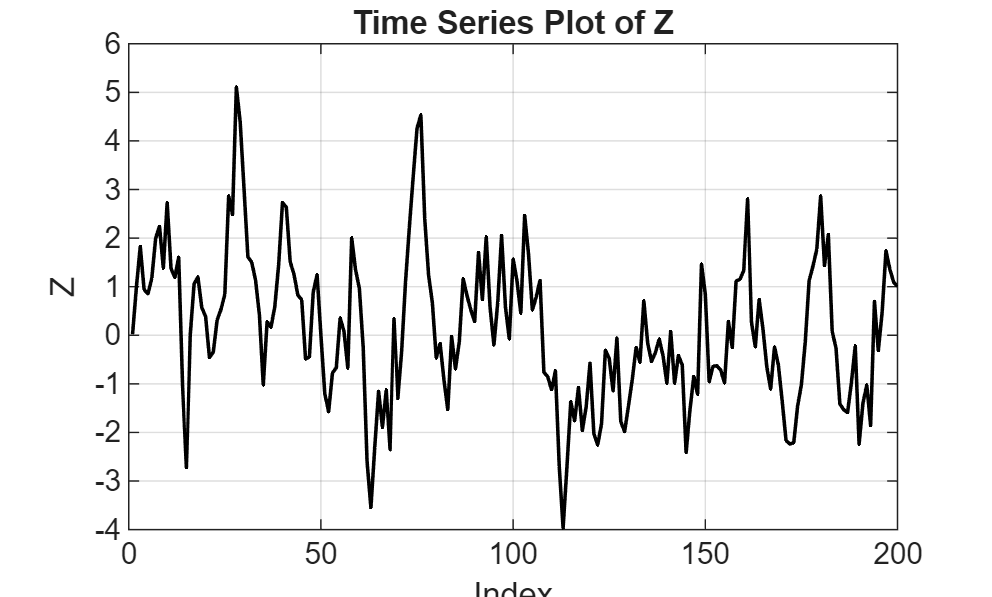


N = numel(Z);

figure;
plot(Z, 'k', 'LineWidth', 1.2);
xlabel('Index');
ylabel('Z');
title('Time Series Plot of Z');
grid on;

The plot shows a stationary, mean-reverting series with short-term serial dependence and some noise — very typical of an AR(p) process.







%% Settings
k     = 5;     % number of folds
Pmax  = 5;     % max AR order
h     = 1;     % 1-step ahead (kept for clarity; design below is 1-step)

%% Build lagged design once (usable rows are Pmax+1..N)
% y(t) = Z_t, X(t,:) = [Z_{t-1}, ..., Z_{t-Pmax}]
Tuse  = (Pmax+1):N;          % usable indices (need Pmax lags)
Nu    = numel(Tuse);         % number of usable rows
y     = Z(Tuse);             % target vector (Nu x 1)
Xall  = zeros(Nu, Pmax);     % lag matrix up to Pmax
for p = 1:Pmax
    Xall(:, p) = Z(Tuse - p);
end

%% Make k contiguous folds directly in the usable index space 1..Nu
% This avoids all mapping/trim edge cases
edges = round(linspace(1, Nu+1, k+1));       % k bins in [1, Nu]
folds = cell(k,1);
for j = 1:k
    folds{j} = edges(j):(edges(j+1)-1);      % contiguous block inside 1..Nu
end

% (Sanity) every fold nonempty?
if any(cellfun(@isempty, folds))
    error('Some folds are empty. Adjust k or check Nu.');
end

%% Storage: RMSFE per (estimation fold j, AR order p)
kfest = NaN(k, Pmax);   % rows: folds, cols: AR order

%% CV loop
for p = 1:Pmax
    Xp = Xall(:, 1:p);  % design for AR(p) (first p lags)

    for j = 1:k
        ins = folds{j};                         % training rows (one fold)
        val = setdiff(1:Nu, ins);               % validation = all other rows

        % Guard: need enough rows to estimate p parameters
        if numel(ins) <= p || isempty(val)
            kfest(j,p) = NaN;
            continue;
        end

        % OLS coefficients (no constant: mirrors arima(..., order=c(p,0,0)) without mean)
        beta = Xp(ins,:) \ y(ins);

        % Vectorized predictions on validation rows
        yhat = Xp(val,:) * beta;                % both are column vectors
        err  = y(val) - yhat;                   % guaranteed matching sizes

        % Fold RMSFE
        kfest(j,p) = sqrt(mean(err.^2));
    end
end

%% Aggregate across folds → one score per AR order
% Option A (common): mean of fold RMSFEs
RMSFE_kfold_mean = mean(kfest, 1, 'omitnan');

% Option B (stricter): recompute overall RMSFE weighting folds by size
% (keeps it simple by averaging squared errors implicitly via per-fold mean)
RMSFE_kfold = RMSFE_kfold_mean;   % choose one; here we expose the mean

%% Display results
disp('RMSFE per fold (rows) and AR order (cols):');

RMSFE per fold (rows) and AR order (cols):


disp(array2table(kfest, ...
    'RowNames',   strcat('fold', string(1:k)), ...
    'VariableNames', strcat('AR', string(1:Pmax))));

               AR1        AR2       AR3        AR4        AR5  
             _______    _______    ______    _______    _______

    fold1    0.99303     1.0058    1.0065    0.99554    0.99604
    fold2    0.97516    0.99372    1.0253     1.0137     1.0144
    fold3     1.0064     1.0181    1.1325     1.1191     1.1142
    fold4      1.057     1.0638    1.0741     1.0503       1.08
    fold5     1.0311     1.0374    1.0473     1.0937     1.1104




disp('Aggregated RMSFE across folds (mean of fold RMSFEs):');

Aggregated RMSFE across folds (mean of fold RMSFEs):


disp(array2table(RMSFE_kfold, 'VariableNames', strcat('AR', string(1:Pmax))));

     AR1       AR2       AR3       AR4       AR5 
    ______    ______    ______    ______    _____

    1.0125    1.0237    1.0571    1.0545    1.063



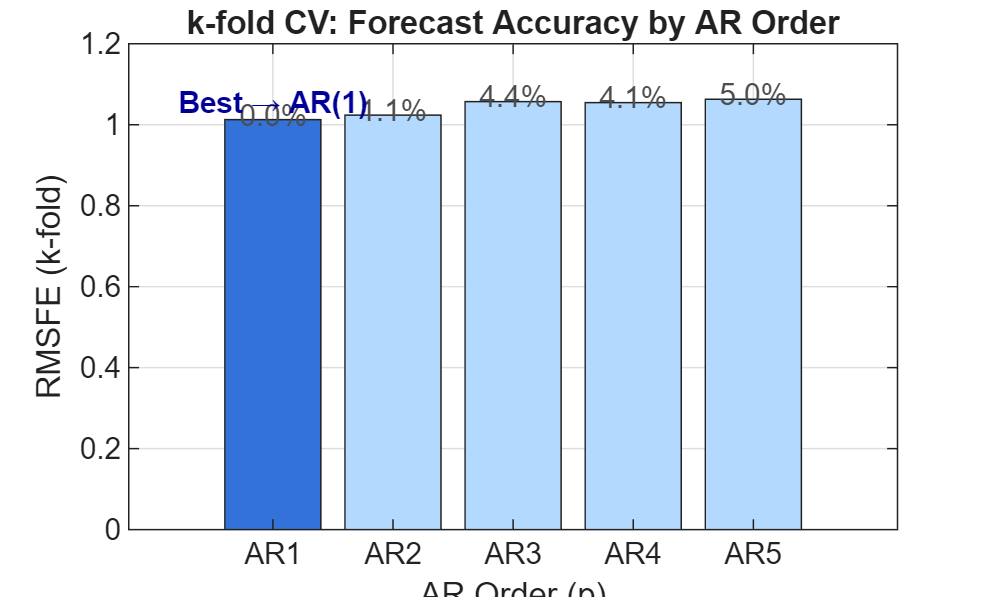


%% Plot with highlighting and % gaps
[minR, bestP] = min(RMSFE_kfold);

figure;
bar(RMSFE_kfold, 'FaceColor', [0.7 0.85 1]); hold on;
bar(bestP, RMSFE_kfold(bestP), 'FaceColor', [0.2 0.45 0.85]);
xlabel('AR Order (p)'); ylabel('RMSFE (k-fold)');
title('k-fold CV: Forecast Accuracy by AR Order');
xticklabels("AR"+string(1:Pmax));
grid on;

% % difference labels w.r.t. the best
percDiff = 100*(RMSFE_kfold/minR - 1);
for p = 1:Pmax
    text(p, RMSFE_kfold(p)*1.01, sprintf('%.1f%%', percDiff(p)), ...
        'HorizontalAlignment','center', 'Color',[0.3 0.3 0.3]);
end
text(bestP, RMSFE_kfold(bestP)*1.04, sprintf('Best → AR(%d)', bestP), ...
    'HorizontalAlignment','center', 'FontWeight','bold', 'Color',[0 0 0.6]);

The k-fold cross-validation plot shows that forecast accuracy is very similar across AR orders, with the lowest RMSFE achieved at AR(p)=bestP, but the differences between AR(1) and higher-order models remain very small.

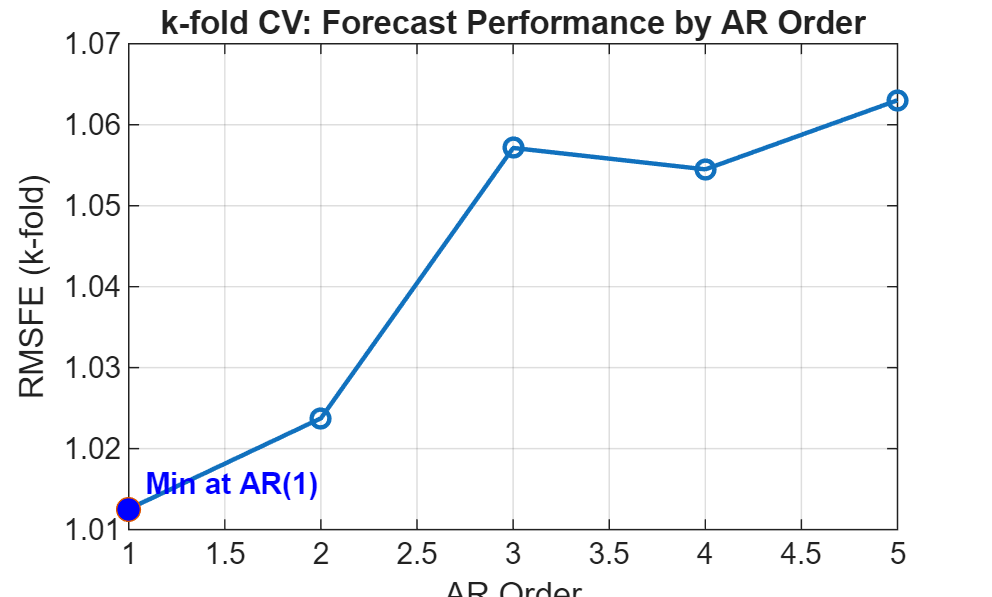



ARorders = 1:Pmax;
[minR, bestP] = min(RMSFE_kfold);

figure;
plot(ARorders, RMSFE_kfold, '-o', 'LineWidth', 1.5);
hold on;

% highlight the best AR order
plot(bestP, RMSFE_kfold(bestP), 'o', ...
     'MarkerSize', 8, 'MarkerFaceColor', 'b');

xlabel('AR Order');
ylabel('RMSFE (k-fold)');
title('k-fold CV: Forecast Performance by AR Order');
grid on;

% optional: text label for the minimum
text(bestP, RMSFE_kfold(bestP)*1.003, ...
     sprintf('  Min at AR(%d)', bestP), ...
     'Color','b','FontWeight','bold');

Moving Block Bootstrap (local function)

function xboot = MBB(x, b)
% Fast Moving Block Bootstrap for a column vector x with block length b.
% Builds all block indices at once; trims to T.
    x = x(:);
    T = numel(x);
    b = max(1, min(b, T-1));              % ensure valid b

    % how many blocks we need to exceed T slightly
    m = ceil((T + b) / b);

    % random start positions (1..T-b+1), inclusive
    starts = randi(T - b + 1, m, 1);      % column vector

    % build block indices matrix: each column is one block of length b
    off = (0:b-1);                         % 1 x b
    idx = starts + off;                    % m x b (implicit expansion)

    % linearize and trim to length T
    idx = reshape(idx.', [], 1);           % (m*b) x 1
    xboot = x(idx(1:T));
end



This exercise demonstrated how different resampling and validation approaches behave in time-series settings and how they support model selection for AR processes. By generating both i.i.d. and AR(1) data, we showed that the simple i.i.d. bootstrap fails to capture dependence, whereas the Moving Block Bootstrap correctly preserves serial correlation and produces more reliable inference for dependent series. The out-of-sample forecasting experiments—recursive, rolling, and k-fold cross-validation—highlighted the importance of evaluating predictive performance rather than relying solely on in-sample fit. Across methods, the results emphasized that low-order autoregressive models are often sufficient, and that slight differences in estimation schemes can shift the preferred order when forecast errors are very close. Altogether, the exercise provides a coherent view of how dependence, resampling design, and validation strategy interact in practical time-series analysis.